# TAIM_1 

## Load Data

load evData.mat

## Draw Data

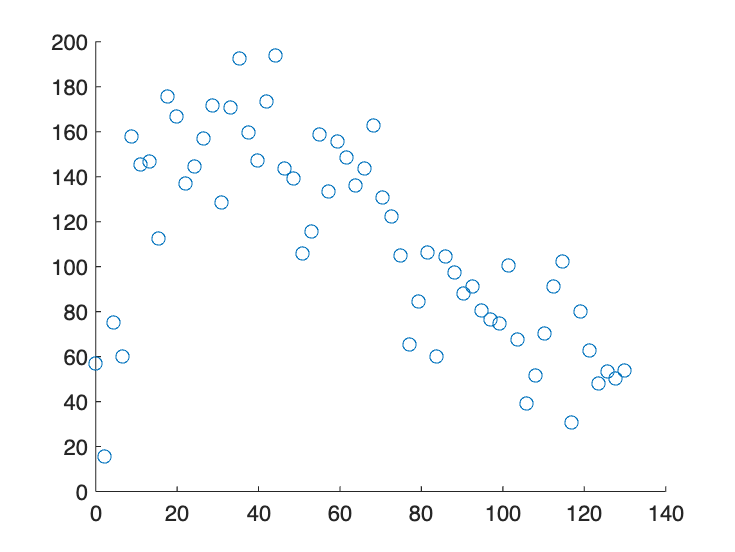

scatter(speed,range)

## First Basic Fitting

We can do a first basic fitting using the plot tools. **Tools > Basic Fitting**

This displays a window to select the type of fitting we want:

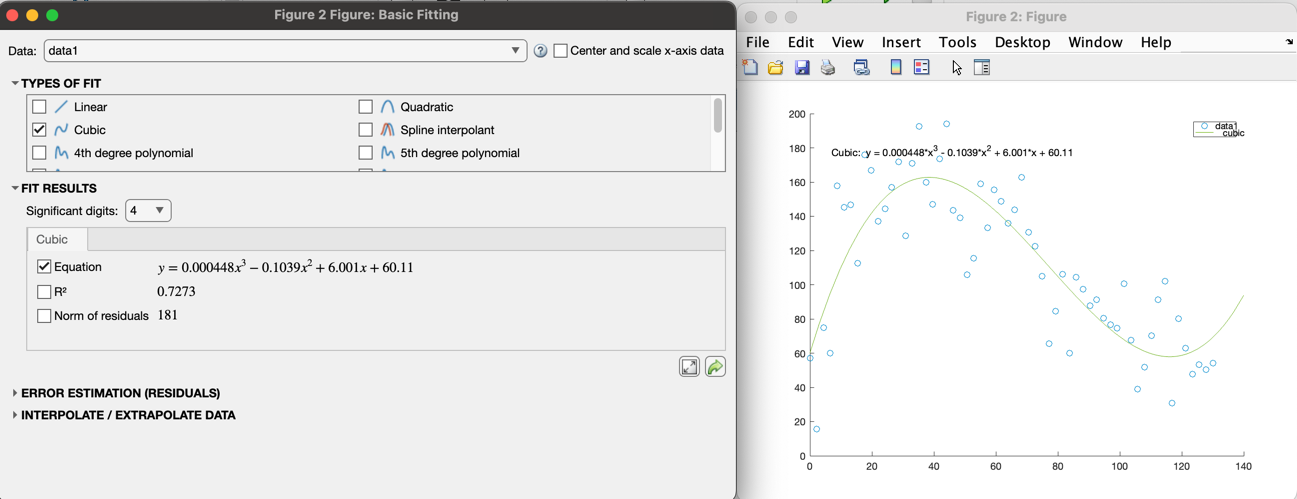

## Better Fitting using Apps

Go to **Apps > Curve Fitter**

Then click **Select Data **and enter the following ranges:

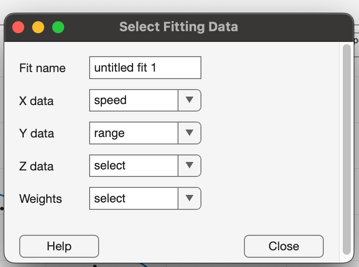

We then create any fittings we want.

Finally, we can **export** the fittings to our workspace.

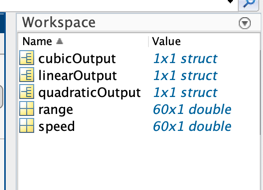

Use the following command to save the fittings in an output: **'save fitOutput.mat cubicOutput quadraticOutput linearOutput' **and they will be created here:

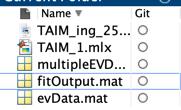

If we used **'save xxx.mat' **we save all of the variables instead of the fittings only.

## Process Results

load fitOutput.mat;

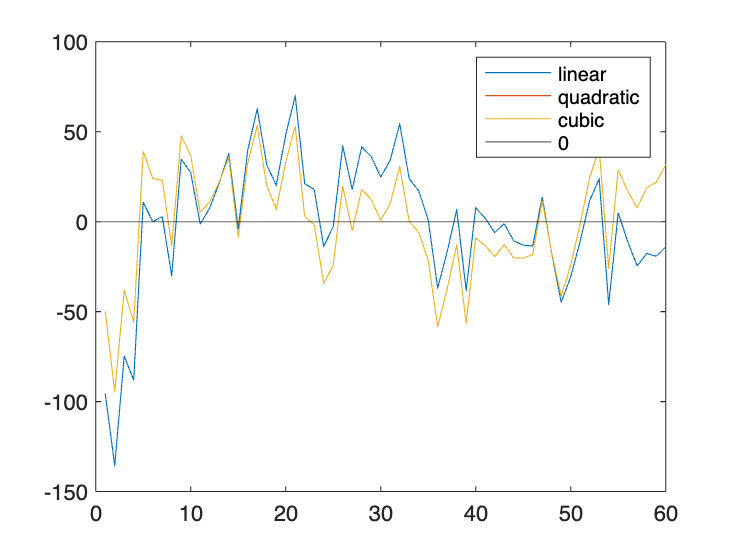

res = linearOutput.residuals;
plot(res)
hold on
resq = quadraticOutput.residuals;
resc = cubicOutput.residuals;
plot(resq)
plot(resc)
yline(0)
hold off
legend(["linear","quadratic","cubic","0"])

## Analysis

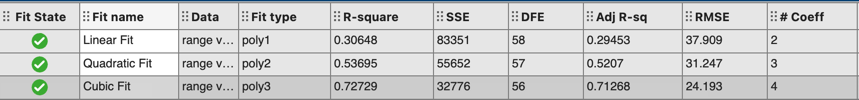

R-Square = 1 when perfect fit

R-Square = 0 when fit does not align at all

SSE = Sum of errors, lower is better

Seeing the results, we can conclude that we should introduce more coefficients to get better results.